startup;

Resetting path to factory state.
Adding "ToolboxToolbox" to path at "/mnt/DataDrive3/emeyer/MATLAB/ToolboxToolbox".


tbUseProject('ISETTreeShrew');

Locating project "ISETTreeShrew" within "/mnt/DataDrive3/emeyer/MATLAB/projects".
  Found at "/mnt/DataDrive3/emeyer/MATLAB/projects/ISETTreeShrew".
Local copy of ToolboxToolbox is up to date.
Updating "ToolboxRegistry".
Already up to date.
Updating "ISETTreeShrew".
Already up to date.
Updating "isetbio".
Your configuration specifies to merge with the ref 'refs/heads/master'
from the remote, but no such ref was fetched.
Updating "UnitTestToolbox".
Already up to date.
Updating "RemoteDataToolbox".
Already up to date.
Updating "ExampleTestToolbox".
Already up to date.
Found "jsonlab_v1.2" and skipping update.
Updating "ISETPipelineToolbox".
Already up to date.
Found "Palamedes_1.8.2" and skipping update.
Resetting path to factory state.
Adding "ToolboxToolbox" to path at "/mnt/DataDrive3/emeyer/MATLAB/ToolboxToolbox".
Adding "ISETTreeShrew" to path at "/mnt/DataDrive3/emeyer/MATLAB/projects/ISETTreeShrew/toolbox".
Adding "ISETTreeShrew" to path at "/mnt/DataDrive3/emeyer/MATLAB/projects/

% Generate default tree shrew optical image
TSoi = oiTreeShrewCreate('opticsType','wvf','name','wvf-based optics');

% Generate default human optical image
HumanOI = oiCreate('wvf human');

% Generate object using display measurements from match-to-sample
% experiment.
presentationDisplay = generateTreeShrewDisplayObject_eemParams();

Loading SPDs from demoSPD.mat
Loading ambient SPD from demoAmbientSPD.mat



% Set image sizes you want to compare
sceneFOVdegs = [1.25,2.5,5,10];

% Integration time
integrationTimeSeconds = 1/1000;

% Set mean luminance and FOV
meanLuminanceCdPerM2 = 20;

% Set number of cone excitation "trials"
nTrialsNum = 100;

% Eccentricity
eccX = 0;
eccY = 0;

% Specify image set
imageSet = 'Kiani_ImageSet_norm';

% Set paths for data and stimuli
conePath = '/mnt/DataDrive2/treeshrew/data_raw/treeshrew_isetbio/coneMosaics';
stimPath = ['/mnt/DataDrive3/emeyer/TreeShrewObjectRecognition/stimulusSets/',imageSet];
catOrder = {'humanbody','humanface','nothumanbody','nothumanface','natural','artificial'};

% Add helper functions to path
cd('/mnt/DataDrive3/emeyer/TreeShrewObjectRecognition/3_retinalModeling/')
addpath(genpath('../helperFunctions/'))

% Initialize cells for cone activations
TSConeAct = cell(length(sceneFOVdegs),1);
humanConeAct = cell(length(sceneFOVdegs),1);

for ss = 1:length(sceneFOVdegs)
    try
        load(sprintf('./activationData/%s/TSConeExcitations_%.2f.mat',imageSet,sceneFOVdegs(ss)),'TSConeAct')
        load(sprintf('./activationData/%s/HumanConeExcitations_%.2f.mat',imageSet,sceneFOVdegs(ss)),'humanConeAct')
    catch
        mosaicFOVdegs = [sceneFOVdegs(ss) sceneFOVdegs(ss)];
        try
            load(sprintf('%s/treeshrew/coneMosaic_deg%.2f.mat',conePath,sceneFOVdegs(ss)),'TSConeMosaic')
        catch
            TSConeMosaic = cMosaicTreeShrewCreate('fovDegs', mosaicFOVdegs,'integrationTime', integrationTimeSeconds,'eccentricityDegs',[eccX,eccY]);
            save(sprintf('%s/treeshrew/coneMosaic_deg%.2f.mat',conePath,sceneFOVdegs(ss)),'TSConeMosaic')
        end
        try
            load(sprintf('%s/human/coneMosaic_deg%.2f.mat',conePath,sceneFOVdegs(ss)),'HumanConeMosaic')
        catch
            HumanConeMosaic = cMosaic('sizeDegs',mosaicFOVdegs,'eccentricityDegs',[eccX,eccY]);
            save(sprintf('%s/human/coneMosaic_deg%.2f.mat',conePath,sceneFOVdegs(ss)),'HumanConeMosaic')
        end

        imIdx = 1;

        for categ = 1:length(catOrder)
            catImgs = dir(sprintf('%s/%s*/',stimPath,catOrder{categ}));
            catImgs = catImgs(~startsWith({catImgs.name}, '.'));
            nImg = length(catImgs);

            for ii = 1:nImg
                imgFile = double(imread([catImgs(ii).folder,filesep,catImgs(ii).name]))./256;

                % Realize scene for image
                realizedStimulusScene = sceneFromFile(imgFile, 'monochrome', ...
                    meanLuminanceCdPerM2, presentationDisplay);

                % Set FOV in scene structure
                realizedStimulusScene = sceneSet(realizedStimulusScene, 'fov', sceneFOVdegs(ss));

                % Compute the tree shrew retinal image
                oi = oiCompute(TSoi, realizedStimulusScene);

                % Compute tree shrew mosaic excitation responses
                [coneAbsorptions,~] = TSConeMosaic.compute(oi, 'nTrials', nTrialsNum);
                TSConeAct{ss}(imIdx,:) = squeeze(coneAbsorptions);

                % Compute the human retinal image
                oi = oiCompute(HumanOI, realizedStimulusScene);

                % Compute human mosaic excitation responses
                [coneAbsorptions,~] = HumanConeMosaic.compute(oi, 'nTrials', nTrialsNum);
                humanConeAct{ss}(imIdx,:) = squeeze(coneAbsorptions);
                imIdx = imIdx+1;
            end
        end
        save(sprintf('./activationData/%s/TSConeExcitations_%.2f.mat',imageSet,sceneFOVdegs(ss)),'TSConeAct','-v7.3')
        save(sprintf('./activationData/%s/HumanConeExcitations_%.2f.mat',imageSet,sceneFOVdegs(ss)),'humanConeAct','-v7.3')
    end
end

	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing the # 

Loading cone mosaic data from /mnt/DataDrive3/emeyer/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/right_eye_cones_58deg_mosaic.


	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing the # of pixels in the stimulus or decrease the stimulus FOV.
	Skipping blur by cone aperture.
	Consider increasing th

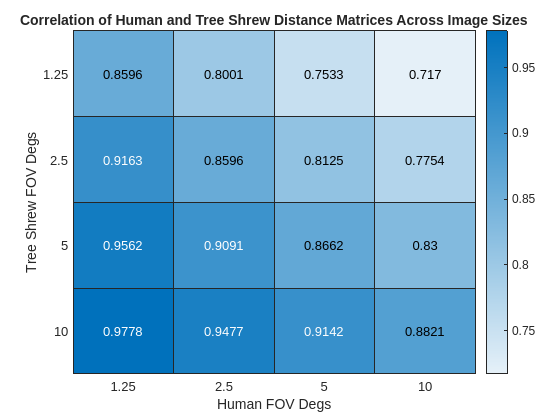

nImgs = size(TSConeAct{1},1);
for ss = 1:length(sceneFOVdegs)
    coneDiff_TS{ss} = pdist2(TSConeAct{ss},TSConeAct{ss});
    coneDiff_human{ss} = pdist2(humanConeAct{ss},humanConeAct{ss});
end

for s1 = 1:length(sceneFOVdegs)
    for s2 = 1:length(sceneFOVdegs)
        TS = tril(coneDiff_TS{s1},-1); TS = TS(TS ~= 0);
        Hum = tril(coneDiff_human{s2},-1); Hum = Hum(Hum ~= 0);
        [r,p] = corr(TS, Hum);
        matCorr(s1,s2) = r;
        pCorr(s1,s2) = p;
    end
end

figure();
heatmap(sceneFOVdegs,sceneFOVdegs,matCorr)
xlabel('Human FOV Degs')
ylabel('Tree Shrew FOV Degs')
title('Correlation of Human and Tree Shrew Distance Matrices Across Image Sizes')